# Dataset generation for identifying a 1 input - 2 outputs transfer function models of a tower crane pilot

H. Garnier - 13/03/2023

This file imports raw data and generates estimation and validation data collected from a square wave experiment applied to a tower crane (Qube-servo 2 equipped with the pendulum) pilot.			

The motions of a rotary pendulum, shown in Figure 3.2, are similar to that of a tower crane. The rotary arm emulates the horizontal jib, the slewing unit is the DC motor, and the pendulum represents the cable carrying a payload. 

The system input is the voltage applied to the DC-motor (in V). 

The two measured outputs are the  rotary arm angle (in rad) and the pendulum angle (in rad).

## First load the data

clear;
load tower_crane_square_test_data
%load tower_crane_square_test_bis_data
%load tower_crane_sine_test_data

The second and third line of the data contain the sampled measurements of  the rotary arm angle and pendulum angle respectively.  

The fourth line contains the sampled measurements of the voltage applied to the D.C. motor. 

The input was generated as a 1 Hz square wave with amplitude of 1V.

The complete input is sent for 10 s.

The first line contains the sampled measurements of the time. 

The sampling interval is Ts=0.002 seconds.

## Plot the raw data

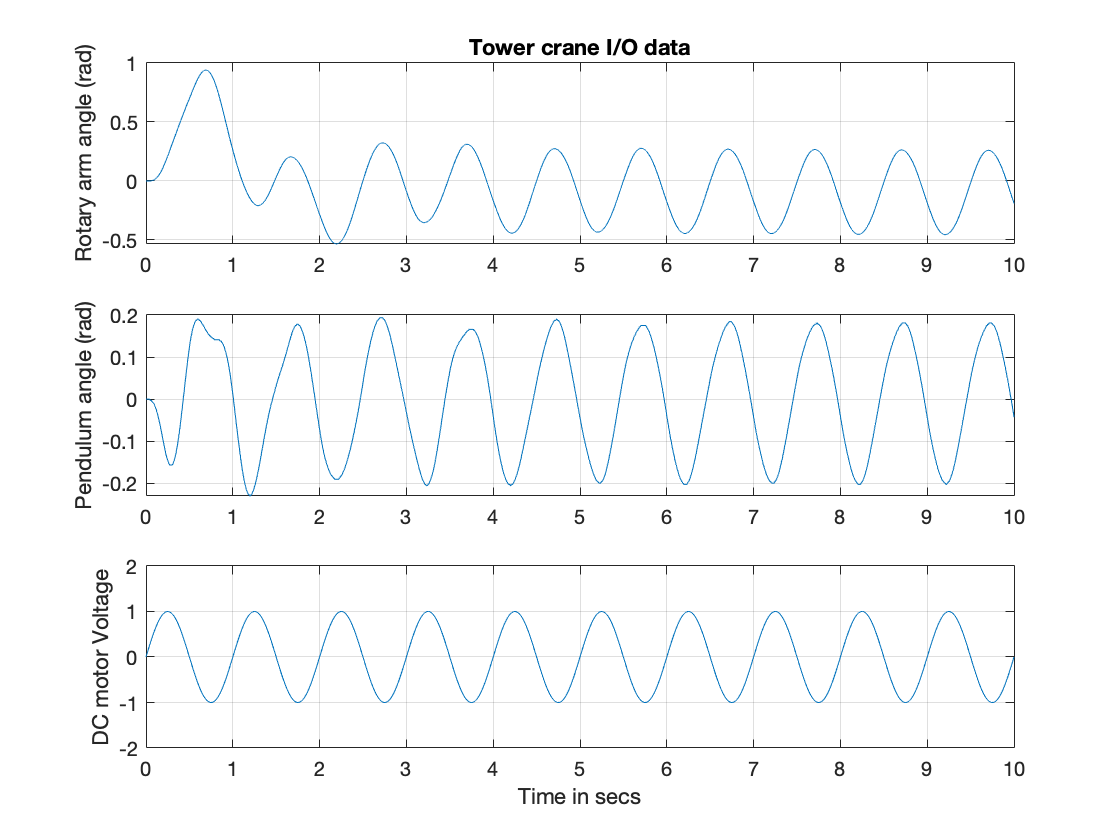

    t=data_crane(1,:)';
    y1=data_crane(2,:)';
    y2=data_crane(3,:)';
    u=data_crane(4,:)';
  
    Ts=0.002;
    N=length(t);
    t=(0:Ts:(N-1)*Ts)';
 		
    subplot(3,1,1)
    plot(t,y1),
    grid
    xlim([0 t(end)])
    title('Tower crane I/O data')
    ylabel('Rotary arm angle (rad)');
    subplot(3,1,2)
    plot(t,y2)
    grid
    ylabel('Pendulum angle (rad)');
    xlim([0 t(end)])
    subplot(3,1,3)
    plot(t,u)
    grid
    ylabel('DC motor Voltage');
    xlabel('Time in secs')
    xlim([0 t(end)])
    ylim([-2 2])